# Exercise 2: Setup Estimation Filter to Track A Single Piece of Space Debris

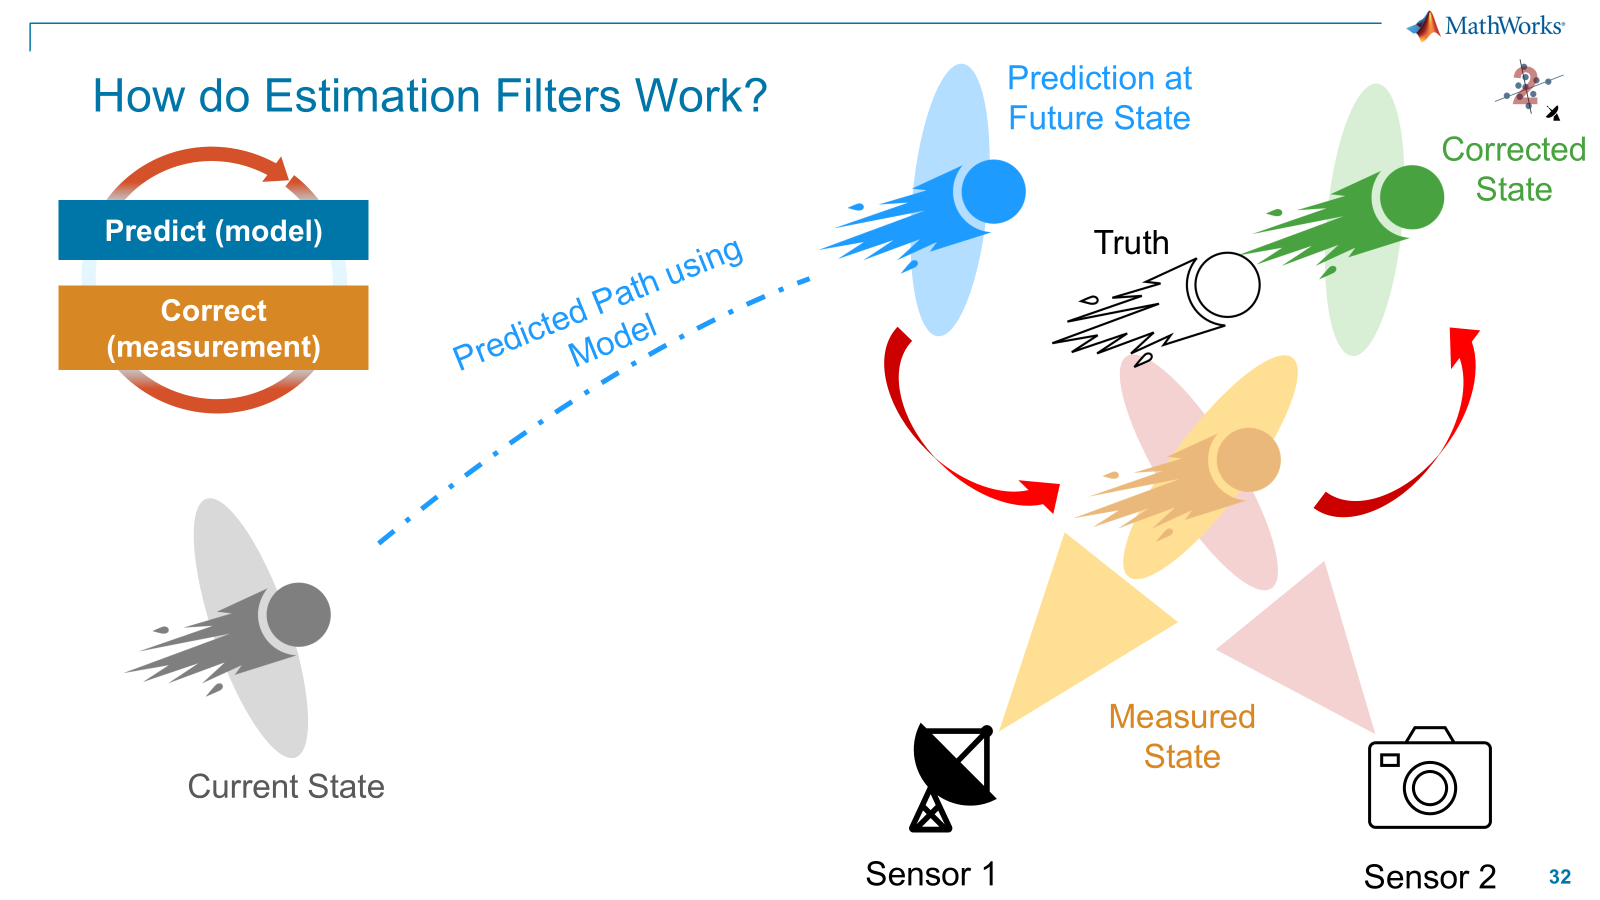

*Note: In the above diagram, we show two sensors, but for this exercise we are only using a single set of detections (implying a single sensor) for simplicity.*

When tracking space debris or any target, estimation filters are commonly used to estimate the **state** of an object.  For tracking applications, a target's **state** commonly consists of some combination of position, velocity, and acceleration. Estimation filters leverage detections (often from sensor measurements), a motion model, and state update equation to predict and correct the future state of the system.

Generally, **Estimation Filters **capture the:

    1) Dynamics of the system via a prediction model (gives the **predicted state**), including the uncertainty of system dynamics (**process noise**) - these are used in the **prediction** step.

    2) Measurements (**detections**), including the uncertainty of the measurements (**measurement noise**) - these are used in the **correction** step.

For more information on state estimation filters, check this documentation page: [Introduction to Estimation Filters](https://www.mathworks.com/help/fusion/ug/introduction-to-estimation-filters.html). Especially, take a look at the flowchart at the bottom of the "Filter Design" section.

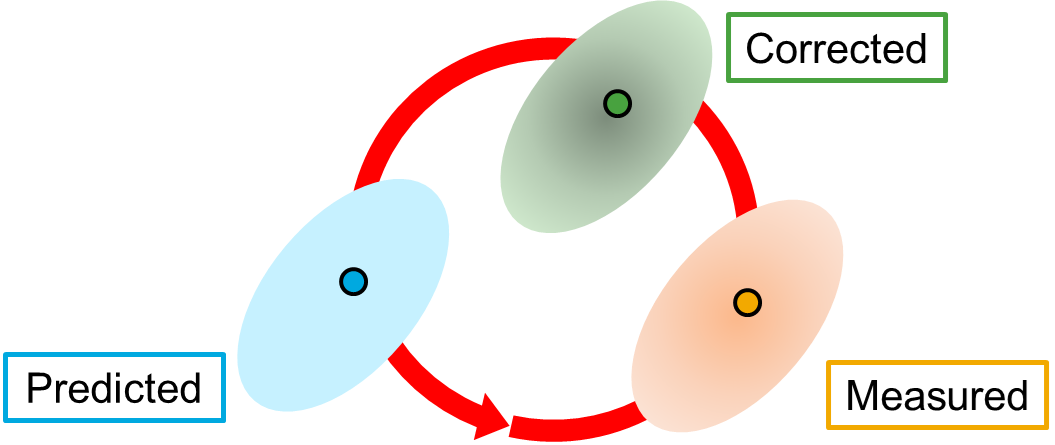

Filters take many forms, but one common filter is the **Extended Kalman Filter**, which we will use in this example. For more information on the Extended Kalman Filter, please check this documentation page: [Extended Kalman Filters.](https://www.mathworks.com/help/releases/R2024b/fusion/ug/extended-kalman-filters.html)

## Exercise 2a: State Estimation Using Default trackingEKF - Where will the debris be in one time step?

First, let's test how the default extended kalman filter performs on our dataset for a single piece of space debris.

We can clear our workspace and command window and also close all open figures with the commands below:

clear; clc; close all;

Let's load in our truth and detection data from the previous example:

load('SpaceDebris4Targets_New.mat')

Now, let's define a filter.

Coding Directions:

Define the estimation filter using a "trackingEKF" filter.  Please create a variable 'filter' that holds the default Extended Kalman Filter (EKF) estimation filter. (HINT: use the "trackingEKF")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% USER CODES THIS:
% type "doc trackingEKF" in the Command Window to find the documentation page for this function

% This filter runs with default inputs
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Plot Detections, Predictions, and Corrections

Loop through the detection data via the time vector to plot detections, predictions, and corrections as the target moves through the space near the radar sensor.

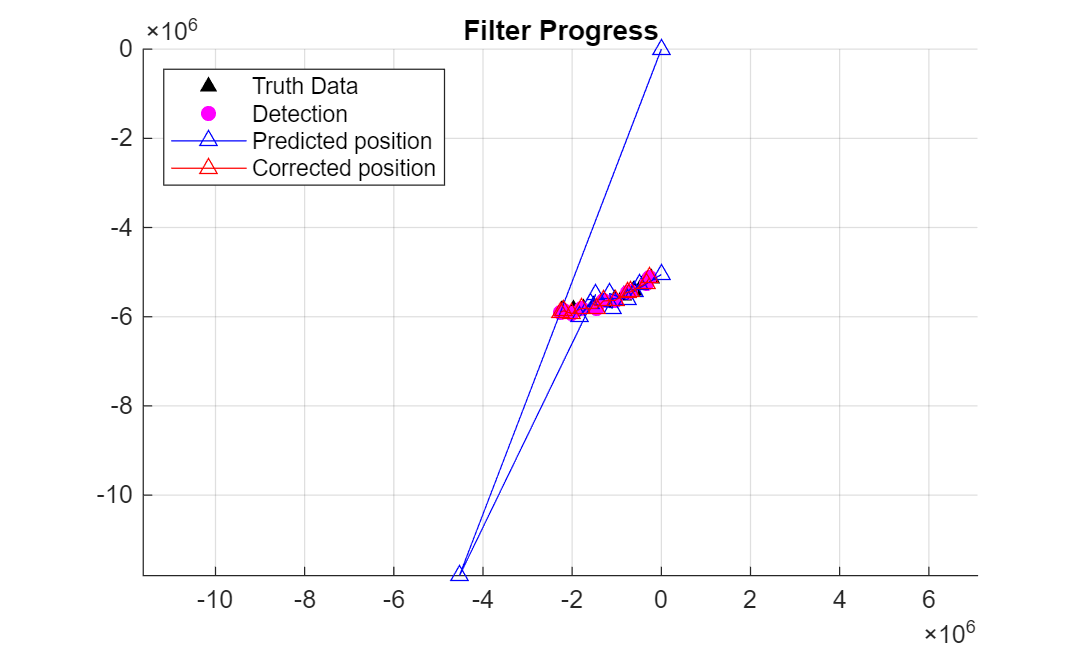

mahalanobisDist = runDataLoop(detPos,truthPos,filter,time,objDet);

Above, we see that our predicted and corrected values are far from the true positions. Remember! These are objects orbiting earth, so the path of the target is long, if our predictions and corrections don't appear exactly over the truth from this vantage point, they must be very far from the truth - on the order of 1e4 meters defined by the space between xticks and yticks on the plot above. We can see that our default filter is not well-tuned to the data. **But how bad is it?**

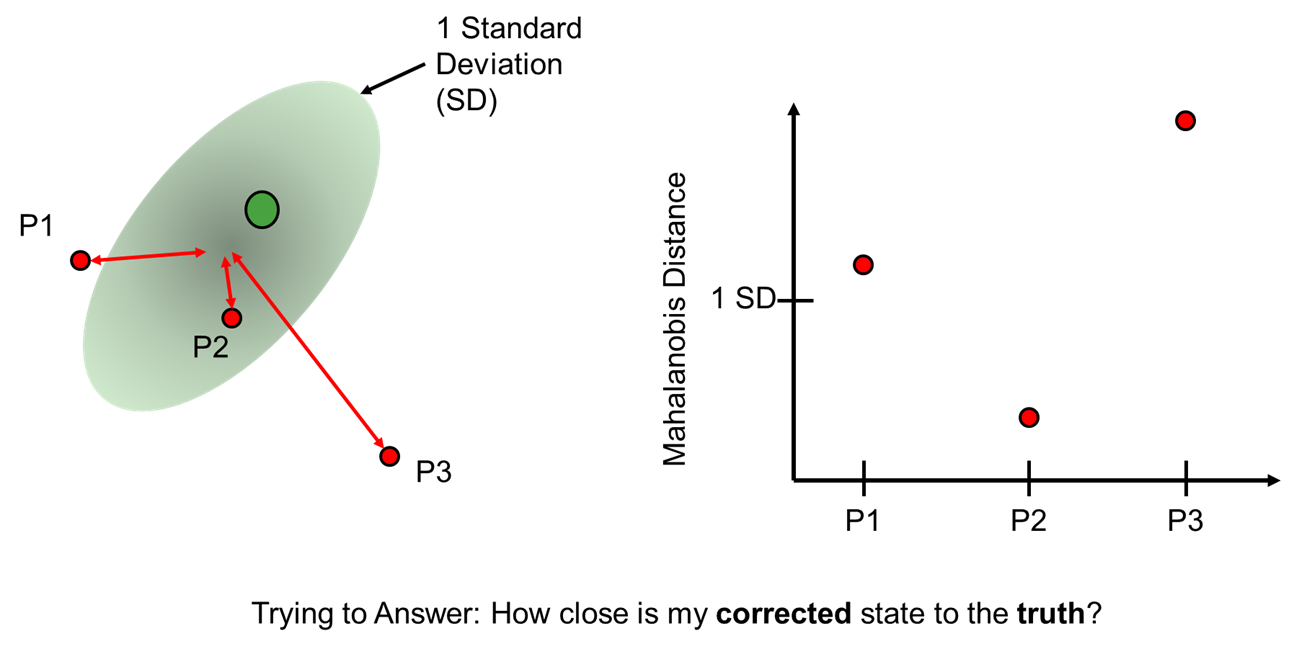

We can use the Mahalanobis Distance to estimate how accurate (or not!) our predicted and corrected positions are.  The Mahalanobis Distance is a measure between a sample point and a distribution, often used within trackers (more on that later). The calculation for the Mahalanobis Distance is within the helper function "plotMahalanobis" at the bottom of this script, if you are interested in the equation, please see [this documentation page](https://www.mathworks.com/help/releases/R2024b/stats/mahal.html?searchPort=58770#d126e790178).

The Mahalanobis Distance is a value relative to a distribution, so a value of 1 means the value of interest (**corrected state**) is 1 standard deviation away from the base value (**truth** **state**).  We see that in our plot below, the **Mahalanobis Distances are very large**.

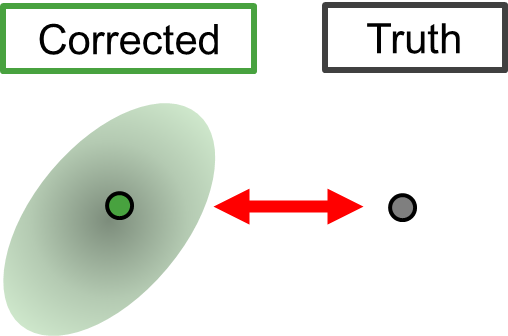

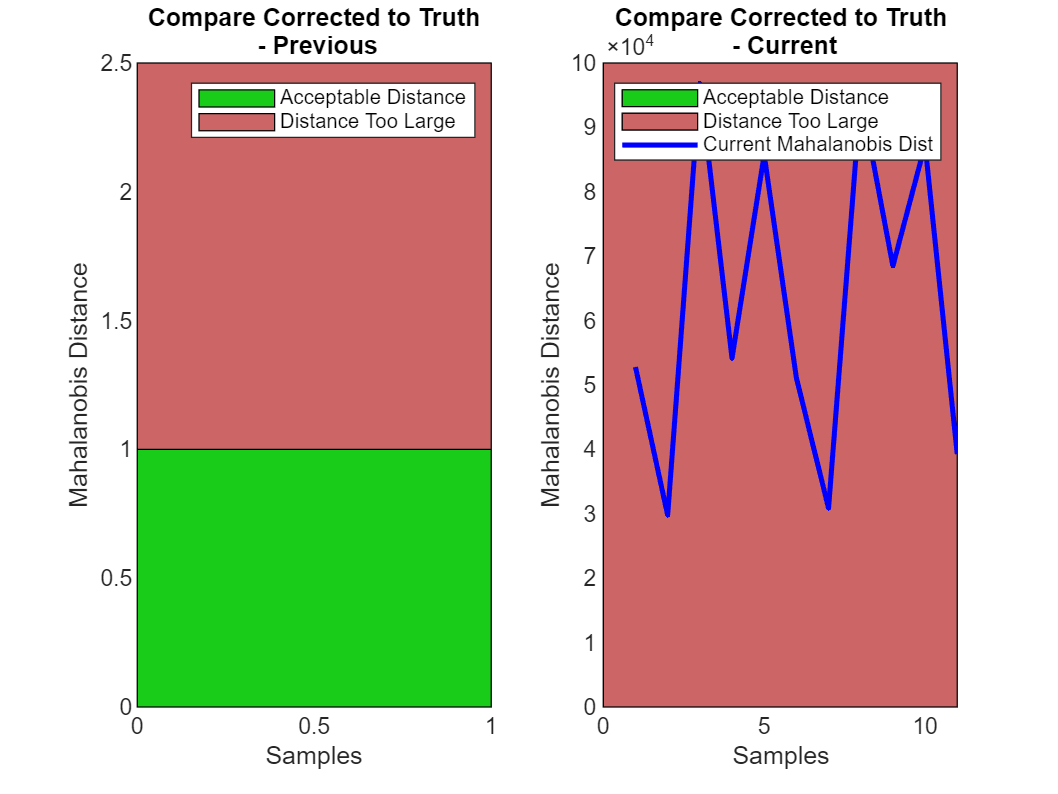

mahDist1  = plotMahalanobisDist(mahalanobisDist,[]);

## Exercise 2b: Improve State Estimation by Adjusting Filter (EKF) Settings 

## With the default trackingEKF settings, we see that our predicted and corrected values don't match our data.** What do we do now?**

To improve our filter, there are a few things we can do:

1) Improve our **initial estimate** of the system and the initial **state covariance** (or the confidence in that estimate).

        a) We can apply the initial detection as the initial state of our system, assuming zero velocity, and this should anchor our filter closer to the true initial state.

        b) Edit values within the **state covariance** matrix to better match the dynamics of the system.  In our constant velocity case, if the filter assumes the target moves slower than it does, the filter may have a tough time predicting the subsequent position of our target.

2) Adjust the **Measurement Noise **to match our detections. Clearly, from our Mahalanobis Distance measurement analysis above, we can tell that our measurements are far from the true positions.  In the 2D plot, we see that our corrected positions are close to the detection positions. Taken together, this suggests that we are not properly considering the measurement noise.  To incorporate the measurement of the detections, we can set the **Measurement Noise** of the filter to the same values as the **Measurement Noise** of the detections.

3) Adjust the **Process Noise **to incorporate the error associated with acceleration, which is not captured using the constant velocity filter. By increasing the process noise, we decrease our confidence in the state predicted by our model

So let's do it!

**Information given by Tracking Engineer:**

initialDetectionPosition = detPos([1 2],1); % 2D position of first detection
detectionMeasurementNoise = objDet{1}.MeasurementNoise;
initialStateCov = blkdiag(detectionMeasurementNoise(1),speed^2/3,detectionMeasurementNoise(1),speed^2/3);
measurementNoise = detectionMeasurementNoise;
processNoise = 1e5;

Setup a new tracker:

filter = trackingEKF;

**1a) Improve Initial Estimate and State Covariance**

Coding Directions: 

Assign the initial position of the detection data "detectionPosition" to the initial state of the filter.

The initial state of the filter is stored in the filter's state immediately after the filter is initialized. You can access this property using "filter.State".  To assign a value to the elements relating to position use the following syntax "filter.State([1 3])"

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% USER CODES THIS:
% type "doc trackerEKF" in the Command Window to find the documentation
% page for this function and look for the "State" Property 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Print out the new initial state estimate:

disp(filter.State)

   1.0e+06 *

   -2.2641
         0
   -5.9034
         0



**1b) Update Initial State Covariance Matrix**

Directions:

1) Assign the initial state covariance matrix to the current state covariance stored within the filter.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% USER CODES THIS:
% type "doc trackerEKF" in the Command Window to find the documentation
% page for this function and look for the "StateCovariance" Property 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Print out the new State Covariance Matrix:

disp(filter.StateCovariance)

   1.0e+09 *

    3.4282         0         0         0
         0    0.0000         0         0
         0         0    3.4282         0
         0         0         0    0.0000



**2) Adjust Measurement Noise Matrix**

The measurement noise is defined relative to the sensor. Often it is dependent on the configuration and physical limits of the sensor.

Directions:

Assign the measurement noise of the sensor to the measurement noise of the filter.  This can be done using the value stored in the variable "detectionMeasurementNoise" above.  Assign this variable to "filter.MeasurementNoise".

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% USER CODES THIS:
% type "doc trackerEKF" in the Command Window to find the documentation 
% page for this function and look for the "MeasurementNoise" Property

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Print out the filter's new measurement noise:

disp(filter.MeasurementNoise)

   1.0e+09 *

    3.4282         0         0
         0    3.4282         0
         0         0    3.4282



**3) Adjust Process Noise Matrix**

Directions:

Assign the process noise given to you by the tracking engineer to the process noise of the filter.  This can be done using the value stored in the variable "accelerationEst" above.  Assign this variable to "filter.ProcessNoise".

**Reminder** that a unit covariance estimated by a gaussian is (b-a)^2/12 and we can assume that a=-b, so this becomes b^2/3, where b is the estimated acceleration.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% USER CODES THIS:
% type "doc trackerEKF" in the Command Window to find the documentation
% page for this function and look for the "Process Noise" Property

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Print out the filter's new process noise:

disp(filter.ProcessNoise)

   1.0e+05 *

    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000



Run through data loop:

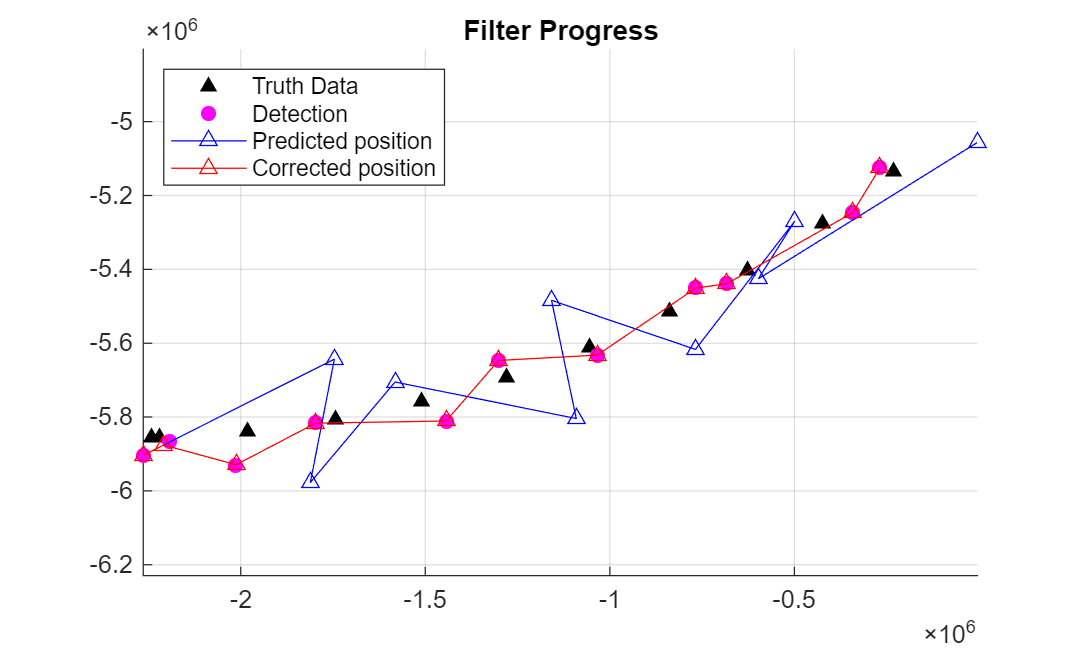

[mahalanobisDist] = runDataLoop(detPos,truthPos,filter,time,objDet);

 Plot Mahalanobis Distance

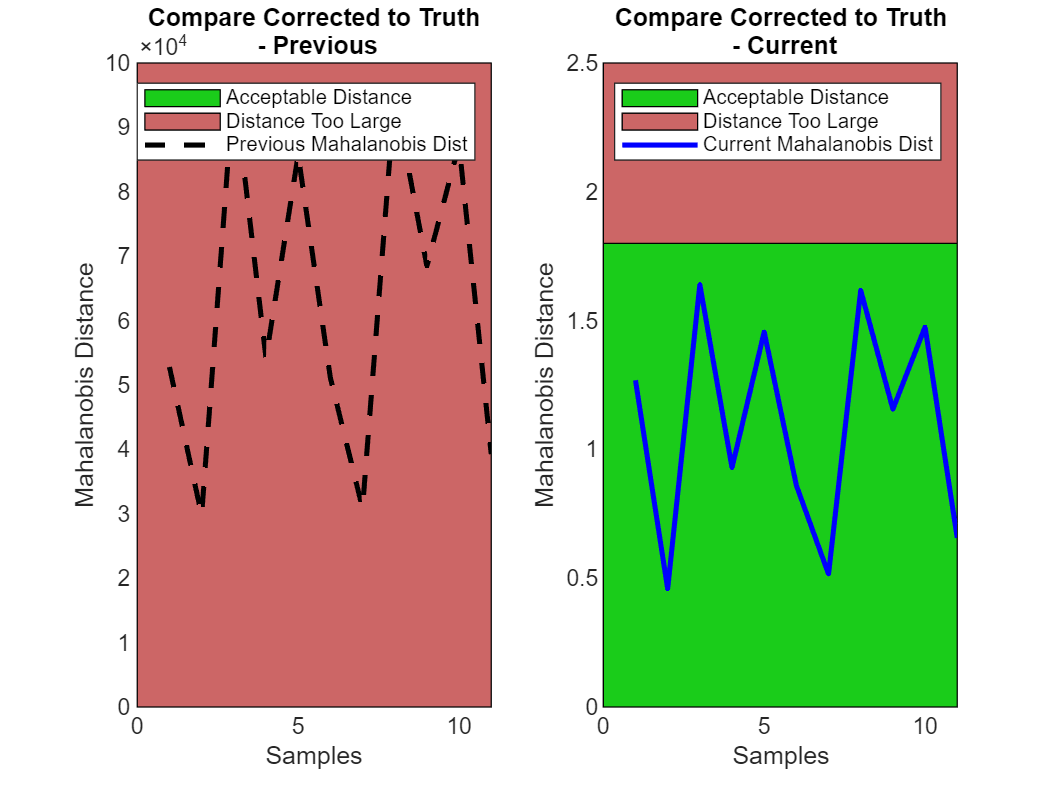

plotMahalanobisDist(mahalanobisDist,mahDist1);

# **Takeaways**

Once we have setup our estimation filter to match the motion of the targets within our scenario, we see that our predicted and corrected locations are close to the detections AND that our Mahalanobis distances are around 1 Standard Deviation. In general, it is critical that the estimation filter is adjusted to match the expected dynamics of the targets that you are tracking.

## **HELPER FUNCTIONS**

**runDataLoop**

function [mahCorrTruth,mahPredMeas,f,pstates,cstates] = runDataLoop(detPos,truthPos,filter,time,objDet)

% Setup Figure to plot in 2D
f=figure; f.Position(3:4) = [1.25e3, 7.5e2]; ax =gca; %ax = subplot(2,2,[1 3]);  
title('Filter Progress'); hold on; grid on; axis equal;%view([29 67]); ax = gca;
%ax2 = subplot(2,2,2); hold on; axis equal;
%ax4 = subplot(2,2,4); hold on; axis equal;

hTrue = []; hPredicted = []; hCorrected = [];
mahPredMeas = []; mahCorrTruth= [];

% % Plot assumed radar sensor location (for reference)
% pos_radar = plot(ax,0,0);
% pos_radar.Marker = 'o';
% pos_radar.MarkerSize = 10;
% pos_radar.MarkerFaceColor = 'g';
% pos_radar.DisplayName = 'Radar Sensor';

% Initialize Delta Time Value:
T = time(2)-time(1);

% Set which 2 of the 3 coordinate directions to be used in this example:
posIDX1 = 1; % X value
posIDX2 = 2; % Y value

% Store first Meas
stateInfo{1,1} = detPos(:,1);

% Store the initial state
stateInfo{1,2} = filter.State;

% Plot the first set of data points to obtain handles and establish legend
hTrue = scatter(ax, truthPos(posIDX1,1), truthPos(posIDX2,1), 'k^', 'filled','DisplayName', 'Truth Data');
hMeasure = scatter(ax, detPos(posIDX1,1), detPos(posIDX2,1), 'mo', 'filled','DisplayName', 'Detection');

% Predict next value
pstates(1,:) = predict(filter, T);

% Store the first predicted state
stateInfo{1,3} = filter.State;

% Store the covariance matrix (for plotting)
pCov{1} = filter.StateCovariance;
hPredicted = plot(ax, pstates(1,1), pstates(1,3), '-^b','DisplayName', 'Predicted position');

% Calculate Mahalanobis
% Predicted versus Measured - Residual to calculate the Mahalanobis Distance
measPos = [detPos([1 2],1); 0]; % NOTE: we have a 2D filter, but cvmeas outputs xyz.  Need to force z value to zero so that filtering is captured properly in 2D of interest
[r, S] = residual(filter, measPos);
mahPredMeas = [mahPredMeas;sqrt(r'/S*r)];

% Correct prediction using the measurement
%cstates(1,:) = correct(filter, detPos(:,1));
cstates(1,:) = correct(filter, [detPos([1 2],1); 0]);

% Store the first corrected state
stateInfo{1,4} = filter.State;

% Store the covariance matrix (for plotting)
cCov{1} = filter.StateCovariance;
% plot corrected state
hCorrected = plot(ax, cstates(1,1), cstates(1,3), '-^r','DisplayName', 'Corrected position');

% Calculate Mahalanobis distance - Corrected versus Truth
% Calculate Position-Only (posnees) form:
e = filter.State([1 3]) - truthPos([1 2],1);
P = filter.StateCovariance([1 3],[1 3]);
mahCorrTruth = [mahCorrTruth;sqrt(e'/P*e)];

% Add legend to plot
%legend([pos_radar, hTrue, hMeasure, hPredicted, hCorrected],'AutoUpdate','off','Location','northwest');
legend([hTrue, hMeasure, hPredicted, hCorrected],'AutoUpdate','off','Location','northwest');

% Initialize time index (we're downsampling data to improve visualization)
nMinus1 = 1;

% Loop through 2nd to final timepoint (above is first timepoint)
% We're not showing all values from the dataset to improve visibility in the plots
sampleCount=0;
desiredSecondPoint = 6;
stateInfoFig = stateInfo;
for n = 2:10:length(time)
    sampleCount = sampleCount+1;

    % Update Telta Time from time vector that matches vector choice above
    T = time(n)-time(nMinus1);
    nMinus1 = n;

    if sampleCount == desiredSecondPoint
        % Store the Measurement
        stateInfo{2,1} = detPos(:,n);
    end
    stateInfoFig{sampleCount+1,1} = detPos(:,n);

    % Plot truth data
    hTrue.XData =  [hTrue.XData truthPos(posIDX1,n)];
    hTrue.YData = [hTrue.YData truthPos(posIDX2,n)];

    % Plot the detections
    hMeasure.XData =  [hMeasure.XData detPos(posIDX1,n)];
    hMeasure.YData = [hMeasure.YData detPos(posIDX2,n)];

    % % Make estimate prediction using predict method of the filter
    pstates(n,:) = predict(filter,T);

    if sampleCount == desiredSecondPoint
        % Store the Predicted State
        stateInfo{2,3} = filter.State;

        % Because there is no "initial state" just store predicted state here too
        stateInfo{2,2} = filter.State;
    end
    stateInfoFig{sampleCount+1,3} = filter.State; % predicted
    stateInfoFig{sampleCount+1,2} = filter.State; % initial

    % Store the covariance matrix (for plotting)
    pCov{sampleCount+1} = filter.StateCovariance;

    % Predicted versus Measured - Residual to calculate the Mahalanobis Distance
    measPos = [detPos([1 2],n); 0]; % NOTE: we have a 2D filter, but cvmeas outputs xyz.  Need to force z value to zero so that filtering is captured properly in 2D of interest
    [r, S] = residual(filter, measPos);
    mahPredMeas = [mahPredMeas;sqrt(r'/S*r)];

    % Plot the predicted state
    hPredicted.XData =  [hPredicted.XData, pstates(n,1)];
    hPredicted.YData = [hPredicted.YData, pstates(n,3)];

    % Correct estimate using detections and the correct method of the filter
    %cstates(n,:) = correct(filter,detPos(:,n));
    cstates(n,:) = correct(filter, [detPos([1 2],n); 0]);

    if sampleCount == desiredSecondPoint
        % Store the Corrected State
        stateInfo{2,4} = filter.State;
    end
    stateInfoFig{sampleCount+1,4} = filter.State; % Corrected

    % Store the covariance matrix (for plotting)
    cCov{sampleCount+1} = filter.StateCovariance;

    % Plot the corrected state
    hCorrected.XData =  [hCorrected.XData, cstates(n,1)];
    hCorrected.YData = [hCorrected.YData , cstates(n,3)];

    % Corrected versus Truth
    % Calculate Position-Only (posnees) form:
    e = filter.State([1 3]) - truthPos([1 2],n);
    P = filter.StateCovariance([1 3],[1 3]);
    mahCorrTruth = [mahCorrTruth;sqrt(e'/P*e)];

end

% Remove zeros -> Reminder, detections were downsampled for viewing
% First, store indices for plotting detections too
bb = any(pstates,2);
idxMeas = find(bb==1);
if bb(1) == 0 % if first state value is all zeros, keep that (bad initial guess case)
    idxMeas = [1;idxMeas]; % initial state may be [0,0,0,0] for defaults, keep this
    storeFirstPState = pstates(1,:);
else
    storeFirstPState = [];
end

pstates( ~any(pstates,2), : ) = [];  %rows
pstates = [storeFirstPState; pstates];
cstates( ~any(cstates,2), : ) = [];  %rows

% % Replot in ax2 - Look at the first detection
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Figure 2,2:
% hTrue = scatter(ax2,truthPos(posIDX1,idxMeas), truthPos(posIDX2,idxMeas), 'k^', 'filled','DisplayName', 'Truth Data');
% hMeasure = scatter(ax2,detPos(posIDX1,idxMeas), detPos(posIDX2,idxMeas), 'mo', 'filled','DisplayName', 'Detection');
% hPredicted = plot(ax2,pstates(:,1), pstates(:,3), '-^b','DisplayName', 'Predicted position');
% hCorrected = plot(ax2,cstates(:,1), cstates(:,3), '-^r','DisplayName', 'Corrected position');
% 
% % Create Confidence Ellipse on last Datapoint
% % Take first term of measurement noise:
% covMatrix = objDet{1}.MeasurementNoise;
% [ellipseMeas,a,b] = createConfidence(covMatrix,detPos,truthPos);
% hold on;
% for jj = 1 %:length(idxMeas) %1:length(detPos)
%     % Measurement
%     plot(ax2,detPos(1,idxMeas(jj)) + ellipseMeas(1, :), detPos(2,idxMeas(jj)) + ellipseMeas(2, :), 'Color', [1 0.5 0.8], 'LineWidth', 2);
%     % Predicted
%     %pCov{jj}
%     [ellipsePred] = createConfidence(pCov{jj},detPos,truthPos);
%     plot(ax2,pstates(jj,1) + ellipsePred(1, :), pstates(jj,3) + ellipsePred(2, :), 'c', 'LineWidth', 2);
%     % Corrected
%     % cCov{jj}
%     [ellipseCorr] = createConfidence(cCov{jj},detPos,truthPos);
%     plot(ax2,cstates(jj,1) + ellipseCorr(1, :), cstates(jj,3) + ellipseCorr(2, :), 'r', 'LineWidth', 2);
% end
% 
% 
% [limsX, limsY] = findLims(stateInfo);
% xlim(ax2,[sort(limsX{1})])
% ylim(ax2,[sort(limsY{1})])
% title(ax2,sprintf('Zoom in on \nFirst Timepoint (Black sq)'))
% 
% % Add rectangle to first, larger figure
% deltaX = abs(limsX{1}(2)-limsX{1}(1));
% deltaY = abs(limsY{1}(2)-limsY{1}(1));
% pos = [limsX{1}(1) limsY{1}(1)  deltaX deltaY];
% rectangle(ax,'Position',pos,'EdgeColor','k')
% 
% hold on;
% deltaX = abs(limsX{2}(2)-limsX{2}(1));
% deltaY = abs(limsY{2}(2)-limsY{2}(1));
% pos = [limsX{2}(1) limsY{2}(1) deltaX deltaY  ];
% rectangle(ax,'Position',pos,'EdgeColor','g')
% 
% % Replot on ax4 - Look at the fourth detection
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Figure 4,4:
% %xlim([-2.1e4 -2e4])
% hTrue = scatter(ax4,truthPos(posIDX1,idxMeas), truthPos(posIDX2,idxMeas), 'k^', 'filled','DisplayName', 'Truth Data');
% hMeasure = scatter(ax4,detPos(posIDX1,idxMeas), detPos(posIDX2,idxMeas), 'mo', 'filled','DisplayName', 'Detection');
% hPredicted = plot(ax4,pstates(:,1), pstates(:,3), '-^b','DisplayName', 'Predicted position');
% hCorrected = plot(ax4,cstates(:,1), cstates(:,3), '-^r','DisplayName', 'Corrected position');
% 
% % Figure 2,2:
% % Create Confidence Ellipse on Fourth Datapoint
% % Take first term of measurement noise:
% covMatrix = objDet{1}.MeasurementNoise;
% [ellipseMeas,a,b] = createConfidence(covMatrix,detPos,truthPos);
% hold on;
% for jj = desiredSecondPoint%1:length(idxMeas) %1:length(detPos)
%     % Measurement
%     plot(ax4,detPos(1,idxMeas(jj)) + ellipseMeas(1, :), detPos(2,idxMeas(jj)) + ellipseMeas(2, :),'Color', [1 0.5 0.8], 'LineWidth', 2);
% end
% 
% for jj = 1:length(pstates)
% 
%     % Predicted
%     [ellipsePred] = createConfidence(covMatrix,detPos,truthPos);
%     plot(ax4,pstates(jj,1) + ellipsePred(1, :), pstates(jj,3) + ellipsePred(2, :), 'c', 'LineWidth', 2);
%     % Corrected
%     [ellipseCorr] = createConfidence(covMatrix,detPos,truthPos);
%     plot(ax4,cstates(jj,1) + ellipseCorr(1, :), cstates(jj,3) + ellipseCorr(2, :), 'r', 'LineWidth', 2);
% end
% xlim(ax4,[sort(limsX{2})])
% ylim(ax4,[sort(limsY{2})])
% title(ax4,sprintf('Zoom in on \n%sth Timepoint (Green sq)',string(desiredSecondPoint)))
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Create figure to click through each point and zoom into truth position
% indices = struct();
% indices.posIDX1 = posIDX1; indices.posIDX2 = posIDX2; indices.idxMeas=idxMeas;

%zoomEachTruth(stateInfoFig,truthPos,detPos,pstates,cstates,covMatrix,pCov,cCov,indices)

end

**plotMahalanobisDist**

function [d2, figHandle]= plotMahalanobisDist(d2,prevD2)

% Instead, plot them as subplots next to one another
figHandle = figure; subplot(1,2,1); hold on; plot(prevD2,'LineWidth',2,'Color','k','LineStyle','--');
ybars = [0 2.5];
ybarsBad = [2.5 max(ylim)];
minX  = min(xlim); maxX = max(xlim);
cla;

patch([minX maxX maxX minX], [ybars(1) ybars(1), ybars(2) ybars(2)], [0.1 0.8 0.1]) % Green, good
patch([minX maxX maxX minX], [ybarsBad(1) ybarsBad(1), ybarsBad(2) ybarsBad(2)], [0.8 0.4 0.4]) % Red, bad

% Repeated plot call to prevent patch from hiding
plot(prevD2,'LineWidth',2,'Color','k','LineStyle','--');
xlabel('Samples')
ylabel('Mahalanobis Distance')
title(sprintf('Compare Corrected to Truth\n - Previous'))

% Create Legend
legend({'Acceptable Distance','Distance Too Large','Previous Mahalanobis Dist',})

% SECOND SUBPLOT
subplot(1,2,2); hold on; plot(d2,'LineWidth',2,'Color','b');
minX  = min(xlim); maxX = max(xlim);
ybarsBad = [2.5 max(ylim)];
cla;

patch([minX maxX maxX minX], [ybars(1) ybars(1), ybars(2) ybars(2)], [0.1 0.8 0.1]) % Green, good
patch([minX maxX maxX minX], [ybarsBad(1) ybarsBad(1), ybarsBad(2) ybarsBad(2)], [0.8 0.4 0.4]) % Red, bad

% Repeated plot call to prevent patch from hiding
plot(d2,'LineWidth',2,'Color','b');
xlabel('Samples')
ylabel('Mahalanobis Distance')
title(sprintf('Compare Corrected to Truth\n - Current'))

% Create Legend
legend({'Acceptable Distance','Distance Too Large','Current Mahalanobis Dist',})

end

**createConfidence**

function [ellipse,a,b] = createConfidence(covMatrix,detPos,truthPos)

if numel(covMatrix) == 9 % In the case of a 3x3 measurement noise matrix
    % Eigen values of measurement noise
    [V, D] = eig(covMatrix); %objDet{1}.MeasurementNoise
    V = V([1 2],[1 2]);
elseif numel(covMatrix) == 16 % In the case of a 4x4 prediction or correction covariance matrix
    [V, D] = eig(covMatrix([1 3],[1 3]));
end

% Calculate sides of ellipse (multiplying by sqrt(5.991) gives 2 SD)
chi_square_val = 1; %sqrt(5.991);
a = chi_square_val * sqrt(D(1,1)); % semi-major axis
b = chi_square_val * sqrt(D(2,2)); % semi-minor axis

% Create ellipse points
theta = linspace(0, 2*pi, 100);
ellipse_x = a * cos(theta);
ellipse_y = b * sin(theta);
ellipse = V * [ellipse_x; ellipse_y];

% fig=figure; hold on;set(fig, 'WindowStyle', 'docked');
% plot(truthPos(1,:),truthPos(2,:),'m*')
% for i = 1:length(detPos)
%     plot(detPos(1,i) + ellipse(1, :), detPos(2,i) + ellipse(2, :), 'r', 'LineWidth', 2);
%     plot(detPos(1,i), detPos(2,i), 'bo'); % plot the detection point
% end
%
% axis equal;
% grid on;
% xlabel('X');
% ylabel('Y');
% title('Confidence Ellipse')
end



**findLims**

function [limsX, limsY] = findLims(stateInfo)
limsX = cell(1,2); limsY = cell(1,2);

for i = 1:2 % x and y coordinates
    % Pull Coords
    % Measured          Initial State       Predicted           Corrected
    xVals = [stateInfo{i,1}(1)  stateInfo{i,2}(1)   stateInfo{i,3}(1)   stateInfo{i,4}(1)];
    yVals = [stateInfo{i,1}(2)  stateInfo{i,2}(3)   stateInfo{i,3}(3)   stateInfo{i,4}(3)];

    % Find bounds
    [minX, maxX] = bounds(xVals);
    [minY, maxY] = bounds(yVals);

    % Is the box going to be small? make at least 2e4/4 square
    minSquareSize = 2.5e5;%2e4/8;

    % Makes rectangles (not squares)
    % diffX = abs(maxX-minX);
    % if diffX < minSquareSize
    %     maxX = maxX + (minSquareSize-diffX)/2;
    %     minX = minX - (minSquareSize-diffX)/2;
    % end
    %
    % diffY = abs(maxY-minY);
    % if diffY < minSquareSize
    %     maxY = maxY + (minSquareSize-diffY)/2;
    %     minY = minY - (minSquareSize-diffY)/2;
    % end

    % Make square
    diffX = abs(maxX-minX);
    diffY = abs(maxY-minY);
    if  diffX < minSquareSize && diffY < minSquareSize
        % Set both to minSquareSize
        maxX = maxX + (minSquareSize-diffX)/2;
        minX = minX - (minSquareSize-diffX)/2;
        maxY = maxY + (minSquareSize-diffY)/2;
        minY = minY - (minSquareSize-diffY)/2;
    elseif diffX < minSquareSize && diffY > minSquareSize
        % Set both to diffY
        maxX = maxX + (diffY-diffX)/2;
        minX = minX - (diffY-diffX)/2;
        maxY = maxY + (diffY-diffY)/2;
        minY = minY - (diffY-diffY)/2;
    elseif diffX > minSquareSize && diffY < minSquareSize
        % Set both to diffX
        maxX = maxX + (diffX-diffX)/2;
        minX = minX - (diffX-diffX)/2;
        maxY = maxY + (diffX-diffY)/2;
        minY = minY - (diffX-diffY)/2;
    elseif diffX > minSquareSize && diffY > minSquareSize
        % Set both to larger of diffX and diffY
        if diffX > diffY
            newVal = diffX;
        else
            newVal = diffY;
        end
        maxX = maxX + (newVal-diffX)/2;
        minX = minX - (newVal-diffX)/2;
        maxY = maxY + (newVal-diffY)/2;
        minY = minY - (newVal-diffY)/2;

    else
        disp('Error - check limits')
    end

    % Package for output
    % limsX{i} = [minX+ minX*0.2, maxX+maxX*0.2];
    % limsY{i} = [minY+ minY*0.2, maxY+maxY*0.2];
    limsX{i} = [minX, maxX];
    limsY{i} = [minY, maxY];
end
end